# Hands-on Tutorial for Global Optimization in Matlab

Heng Yang

Massachusetts Institute of Technology

Download Now: [https://tinyurl.com/GlobalOptimization](https://tinyurl.com/GlobalOptimization) 

This hands-on tutorial gives an example on how to use global optimization tools in Matlab. It uses the rotation averaging problem as an illustrative example and shows that this problem can be solved to *global optimality with certificates*, using *semidefinite relaxation*. Further, it demonstrates that large-scale semidefinite programming can be solved fast by exploiting low-rank structure of the solution.

## Rotation Averaging:Recap 

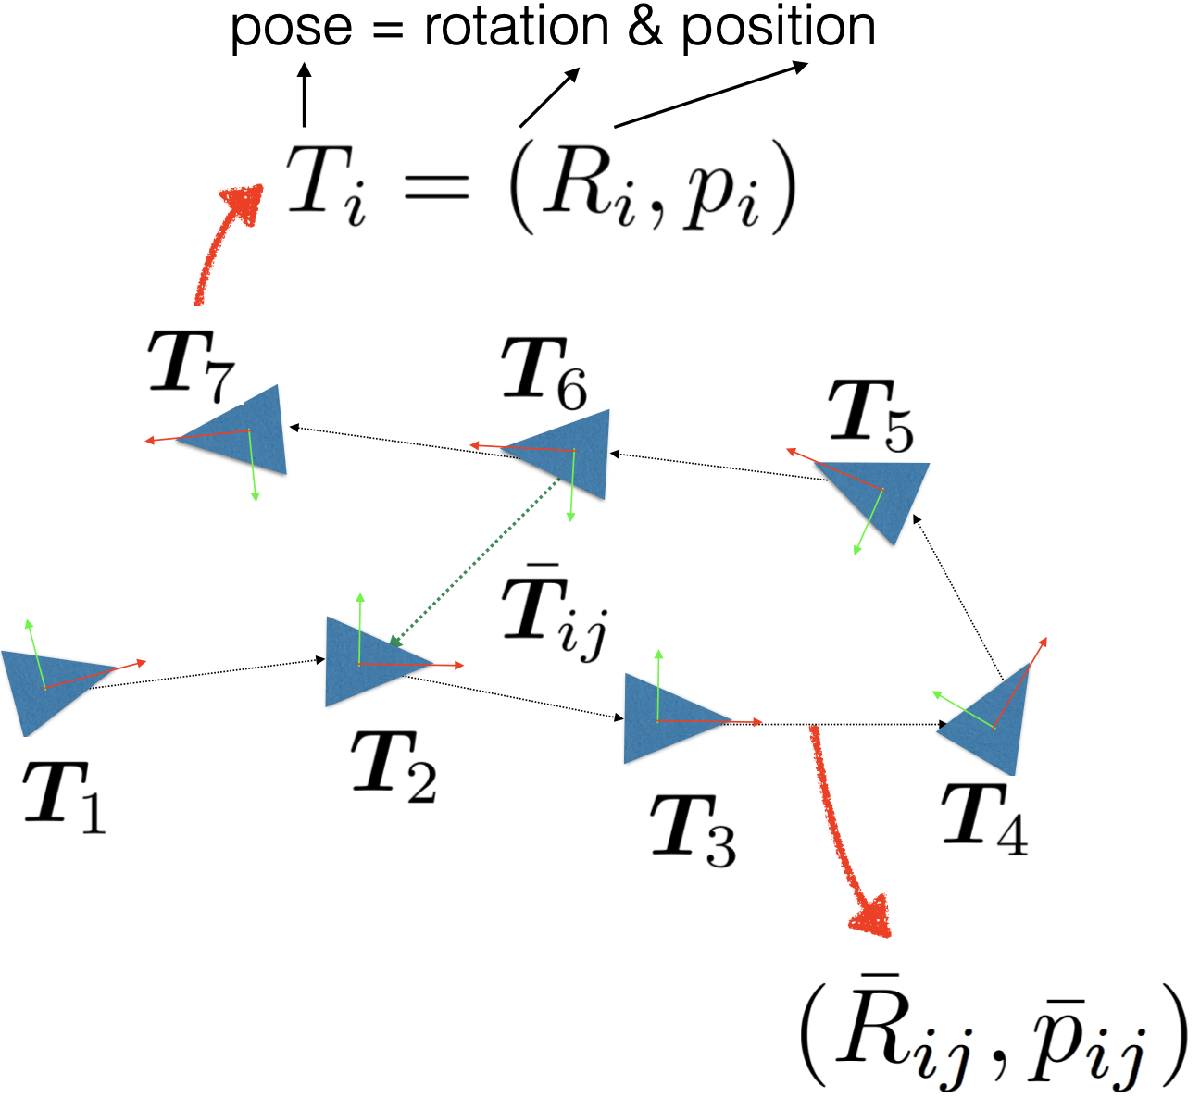

The problem of rotation averaging is defined as the task of **determining a set of **$n$** absolute rotations **$R_1,\dots,R_n, R_i \in SO(d)$, **given distinct estimated relative rotations **$\tilde{R}_{ij} \in SO(d)$, where $SO(d) \doteq \{R \in \mathbb{R}^{d \times d} | RR^T = R^TR = I_d, det(R)=+1\}$ is the S*pecial Orthogonal* group of dimension $d=\{2,3\}$ that contains proper rotation matrices. We can **define a graph** $G=(V,E)$, where each vertex $i \in V$ is assigned an absolute rotation $R_i$, and each edge $(i,j) \in E$ is assigned a relative rotation $\tilde{R}_{ij}$. 

In the absence of measurement noise, it holds that 

$R_i \tilde{R}_{ij} = R_j$, for all $(i,j) \in E$. (1)

However, due to measurement noise, we do not expect the above equation to be true. Therefore, to obtain the optimal estimation of absolute rotations at each vertex, we adopt a least squares estimation:

$R_1^\star,\dots,R_n^\star =\text{argmin}_{R_1,\dots,R_n \in SO(d)} \sum_{(i,j) \in E} \| R_i \tilde{R}_{ij} - R_j \|_F^2$. (**2-Least Squares Estimation**)

where $\| R_i \tilde{R}_{ij} - R_j \|_F$ denotes the **chordal distance** between two rotations $R_i \tilde{R}_{ij}$ and $R_j$ (in the absence of noise, the chordal distance is zero due to Eq. (1)). With straightforward calculations, the optimization (2) can be simplified as:

$R_1^\star,\dots,R_n^\star =\text{argmin}_{R_1,\dots,R_n \in SO(d)} \quad 2d|E| - 2\sum_{(i,j) \in E} \text{tr} \left( R_i \tilde{R}_{ij}R_j^T \right)$. (3)

where $|E|$ denotes the cardinality of the edge set $E$. Since the constant $2d|E|$ will not affect the result of the optimization, the final optimization problem is:

$R_1^\star,\dots,R_n^\star =\text{argmin}_{R_1,\dots,R_n \in SO(d)} \quad - \sum_{(i,j) \in E} \text{tr} \left( R_i \tilde{R}_{ij}R_j^T \right)$. **(4-Rotation Averaging)**

Due to the non-convexity of $SO(d)$ constraints, it is hard to globally optimize problem (4). Our goal is to apply semidefinite relaxation so that we arrive at a convex SDP. Before applying SDP relaxation, we first write the problem as a quadratically constrained quadratic program (QCQP).

## Quadratically Constrained Quadratic Program (QCQP)

The first simplification we apply is to remove the determinant constraint in $SO(d)$ and replace it with $O(d)$:

$R_1^\star,\dots,R_n^\star =\text{argmin}_{R_1,\dots,R_n} \quad - \sum_{(i,j) \in E} \text{tr} \left( R_i \tilde{R}_{ij}R_j^T \right) \\
\quad\text{subject to }\quad R_i R_i^T = I_d, \forall i=1,\dots,n$**(5-Drop Determinant)**

where we have explicitly written the $R_i \in O(d)$ constraint as $R_i R_i^T = I_d$. Now we can stack all the unknown rotations $R_1,\dots,R_n$ into a single matrix $R$:

$R = \left[ \begin{array}{c} R_1 \\ R_2 \\ \vdots \\ R_n 
\end{array} \right] \in O(d)^n \subset \mathbb{R}^{dn \times d}$.

and all the measurements $\tilde{R}_{ij}$ into a single matrix $\bar{Q}$ (also including the "$-$" sign of the cost function):

$\bar{Q} = \left[ \begin{array}{cccc}
0 & -a_{12}\tilde{R}_{12} & \dots & -a_{1n}\tilde{R}_{1n} \\
-a_{21}\tilde{R}_{21} & 0 & \dots & -a_{2n} \tilde{R}_{2n} \\
\vdots & \vdots & \ddots & \vdots \\
-a_{n1} \tilde{R}_{n1} & -a_{n2} \tilde{R}_{n2} & \dots & 0
\end{array}\right]$, (Q_bar)

where $\tilde{R}_{ij} = \tilde{R^T}_{ji}$ and $a_{ij} = 1$if $(i,j) \in E$, $a_{ij} = 0$ if $(i,j) \notin E$. Then problem (5) is equivalent to the following optimization:

$R^\star = \text{argmin}_{R} \quad \text{tr}\left( \bar{Q} R R^T\right) \\
\quad \text{subject to } \quad R \in O(d)^n$ (**6-QCQP**).

Problem (6) is a QCQP because both the objective function and the constraints are quadratic functions of the unknown $R$.

## Semidefinite Relaxation

Once we arrive at a QCQP, applying the semidefinite relaxation is straightforward. 

### Step 1: Lift

**The first step is the lifting step (Quadratic becomes Linear!)**. In this step, we create a new matrix variable $Z = RR^T$:

$Z = R R^T = 
\left[ \begin{array}{c} R_1 \\ R_2 \\ \vdots \\ R_n
\end{array} \right] 
\left[ \begin{array}{cccc} R_1^T &  R_2^T & \cdots  & R_n^T 
\end{array} \right] 
= \left[ \begin{array}{cccc}
R_1R_1^T & R_1 R_2^T & \dots & R_1 R_n^T \\
\star & R_2R_2^T & \dots & R_2R_n^T \\
\vdots & \vdots & \ddots & \vdots \\
\star & \star & \dots & R_nR_n^T
\end{array}\right] = 
\left[ \begin{array}{cccc}
I_d & R_1 R_2^T & \dots & R_1 R_n^T \\
\star & I_d & \dots & R_2R_n^T \\
\vdots & \vdots & \ddots & \vdots \\
\star & \star & \dots & I_d
\end{array}\right] $(7)

where the second equality comes from the constraint that $R \in O(d)^n$. Eq. (7) shows that the diagonal $d\times d$ blocks of matrix $Z$, denoted as $[Z]_{ii}$, are all identity matrices. At the same time, by the construction $Z = RR^T$($Z$ is called the gram matrix of $R$), we have:


$$Z \succeq 0 \\
\text{rank}(Z) = d$$


In fact, one can show that $[Z]_{ii}=I_d, Z\succeq 0, \text{rank}(Z)=d$ is equivalent to saying that $Z$ has a rank $d$ factorization $Z = R R^T$ such that $R \in O(d)^n$. Therefore, Problem (6) is equivalent to the following rank-constrained optimization:

$R^\star (R^\star)^T = Z^\star = \text{argmin}_{Z} \quad \text{tr}\left( \bar{Q} Z \right) \\
\quad \text{subject to} \quad Z \succeq 0 \\
\quad \quad \quad \quad \quad [Z]_{ii} = I_d, \forall i=1\dots,n \\
\quad \quad \quad \quad \quad\text{rank}(Z) = d$(**8-Rank-Constained SDP**)

Problem (8) is NP-hard in general due to the non-convex rank constraint. 

### Step 2: Drop

**The second step is the dropping step, in which we drop the rank constraint.** Then we arrive at a **convex semidefinite program** that we know how to solve in polynomial time:

$R^\star (R^\star)^T = Z^\star = \text{argmin}_{Z} \quad \text{tr}\left( \bar{Q} Z \right) \\
\quad \text{subject to} \quad Z \succeq 0 \\
\quad \quad \quad \quad \quad [Z]_{ii} = I_d, \forall i=1\dots,n$ **(9-SDP Relaxation) **

Problem (9) can be readily implemented in Matlab and solved to global minimum. However, usually an SDP relaxation can only guaranttee a lower bound of the original non-convex problem, which means that the optimal cost of Problem (9), $f^\star_{SDP}$, is a lower bound for the optimal cost of problem (8) and problem (6) $f^\star$:

$f^\star_{SDP} \leq f^\star$.

However, due to the structure of the rotation averaging problem, solving the SDP (9) actually solves the original pronblem (8) exactly. 

### Step 3: Certify Global Optimality

**The third step is to certify global optimality by checking the rank of the solution of the SDP**. If $\text{rank}(Z^\star) = d$, then this means that dropping the rank constraint actually does not affect the optimization, because we end up with a rank $d$ solution. 

### Step 4: Round

**The last step is called rounding**, which is to extract solution to the original non-convex problem given solution of the SDP. Using the rank $d$ solution of the SDP, we can factorize $Z^\star = R_{est} R_{est}^T$ and extract the solution to the original nonconvex problem (note that the factorization is not unique unless we fix the first rotation $R_1$ to be identity). It is usually the case that $R_{est}$ may not satisfy the original non-convex constraints, therefore, we sometimes need to project $R_{est}$ into the feasible set of the original optimization (in the rotation averaging case, project to $SO(d)$). Using (the projected) $R_{est}$, we can evaluate the objective function and obtain the estimated cost $f_{est}$, then we have the following inequality:

$f^\star_{SDP} \leq f^\star \leq f_{est}$ **(10-Weak Duality)**

where the first inequality comes from the SDP relaxation and the second inequality comes from the fact the $f^\star$ is the global minimum and hence must be smaller than the objective function evaluated at any point inside the feasible set. Using eq. (10), we can also calculate the relative duality gap:

$\text{relative duality gap} = \frac{f_{est} - f^\star_{SDP}}{f_{est}}$ (11)

The smaller the relaitive duality gap is, the tighter the SDP relaxation is. When the relative duality gap is zero, we can also certify global optimality and strong duality. In the next section, we will implement the SDP relaxation in Matlab. 

## Matlab Implementation

**Prerequisite:** Please [download CVX](http://cvxr.com/cvx/download/) and put the folder at the same level as `GlobalOptimizationTutorial`, then run `cvx_setup` from the Matlab console in the `cvx` folder.

We first setup this tutorial.

% setup path and start clean
setup
clc; clear; close all;

For a first example, let us consider rotation averaging on a simple 2D grid graph with noisy relative rotation and translation measurements. The following code snippt generates a random 2D grid graph, with ground truth poses, and the first rotation $R_1$ is set to be identity.

% build a random grid graph
d = 2; % 2D planar graph
nrNodes = 200; % graph has n = 100 vertices
probLC = 0.8; % probability of loop closures in the grid graph
rotStd = 0.01; % noise standard deviation for rotation
tranStd = 0.01; % noise standard deviation for translation
graph = grid_random_graph_2D(nrNodes, ...
            'RotationStd', rotStd, ...
            'TranslationStd', tranStd, ...
            'Scale', 1.0, ...
            'LoopClosureProbability', probLC);
nrEdges = size(graph.edges,1);
% save the ground-truth rotations
R_gt = zeros(d*nrNodes,d);
for i=1:nrNodes
   R_gt(blkIndices(i,d),:) = rot2D(graph.poses_gt(i,3)); 
end
if norm(R_gt(1:2,1:2,1)-eye(2)) > 1e-6
   error('first rotation != identity') 
end
fprintf(['Random 2D grid graph: number of nodes: %d, ' ...
    'number of edges: %d.\n'], ...
    nrNodes, nrEdges);

Random 2D grid graph: number of nodes: 200, number of edges: 331.


In the rotation averaging problem, we will not estimate the full pose (rotation and translation) of each node, but only focus on estimating the rotation of each node (one can actually marginalize out translations first). 

In the `lib` folder, we provide a procedure `build_data_matrix` that builds the matrix $\bar{Q}$ from edge measurements $\tilde{R}_{ij}$. The following line build the data matrix $\bar{Q}$ from the edge measurements, and the readers can check the sparsity pattern satisfies Eq. (Q_bar).

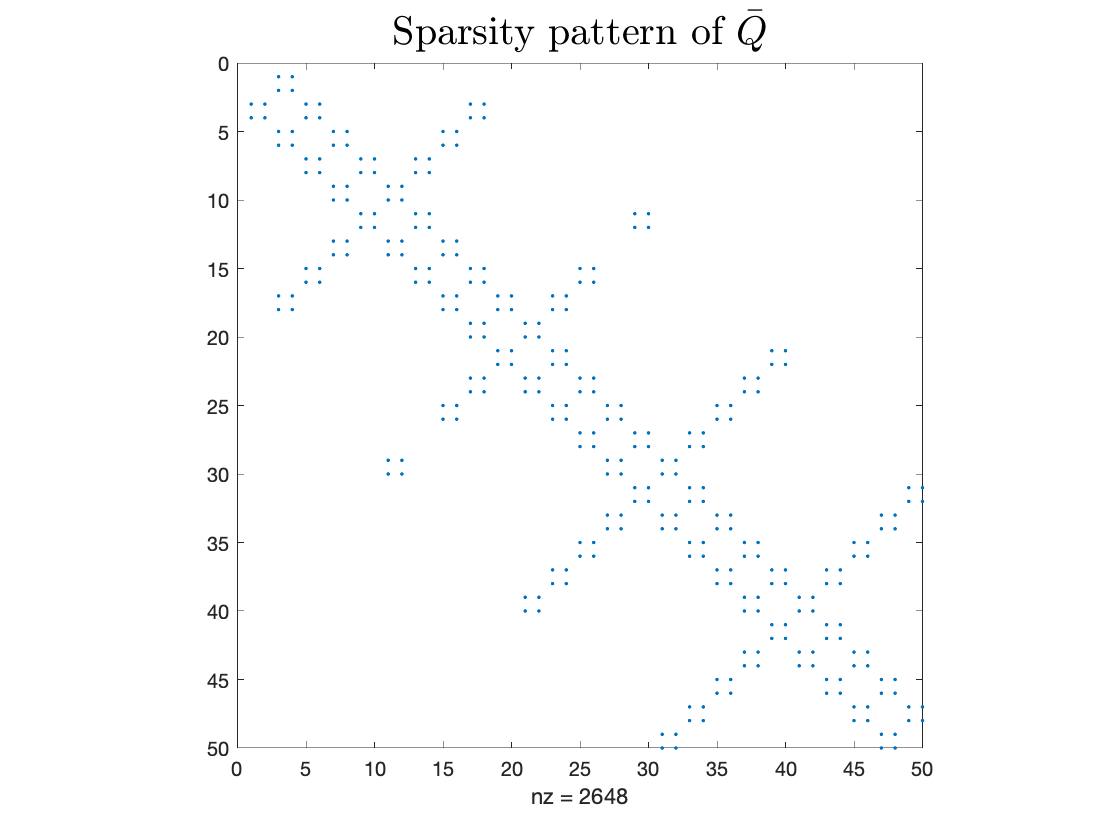

% build the data matrix R_tilde (d=2 for 2D planar graph)
Q_bar = build_data_matrix(graph.edges,nrNodes,d);
spy(Q_bar); 
ylim([0, 50]), xlim([0,50]); % only visualize part of the sparsity pattern
title('Sparsity pattern of $\bar{Q}$',...
    'Interpreter','latex','fontsize',20) 

Now we are ready to implement the core part of our algorithm -- solving the SDP relaxation in problem (9), using the random generated data matrix $\tilde{R}$:

% implement the SDP in problem (9)
t_start = tic; 

% start CVX modelling

% define the decision variable Z

% define the objective function (we include the constant term in Eq.(3) as well)

% define the constraints of the SDP

% then solve the SDP!

t_sdp = toc(t_start);

Now we can extract solutions of the SDP and check if the relaxation is exact:

% extract SDP solutions and check relaxation tightness
  
% bar-plot eigenvalues

Because the rank of the SDP solution $\text{rank}(Z^\star) = d= 2$, we can certify that the relaxation is indeed exact/tight! Now we can extract the optimal solution to the original non-convex problem (6) from the SDP solution. Because the first rotation $R_1 = I_d$ is identity, from Eq. (7) we can see that the first block row of $Z$ contains all the rotation matrices $R_2,\dots,R_n$.

% Extract solution to the original problem from SDP solution
R_est = repmat(eye(d), [nrNodes,1]);

% evaluate the objective function on R_est to get f_est

% compute relative duality gap

% print information

From this result, we see that the relative duality gap is indeed zero (up to numerical accuracy). Now we can compare the estimated rotations with the ground-truth rotations to see how accurate our estimation is.

R_err = rad2deg( get_rot_error(R_est,R_gt,d) );
min_R_err = min(R_err);
max_R_err = max(R_err);
mean_R_err = mean(R_err);
fprintf(['SDP estimation: min R_err = %g[deg], ' ...
    'max R_err = %g[deg], mean R_err = %g[deg].\n'],...
    min_R_err,max_R_err,mean_R_err);

SDP estimation: min R_err = 0[deg], max R_err = 177.466[deg], mean R_err = 86.2133[deg].


## Fast Low-Rank SDP Solver

### Solve Pose Graph Optimization on 2D Grids

We now use SE-Sync to solve the above problem and show that exploiting the low-rank and manifold property of the SDP structure can significantly speed up the process of solving large-scale SDP. 

% convert data to SE-Sync type
sesync_measurements = convert2sesync(graph.measurements);
% default solver settings for SE-Sync and Manopt
default_solver_settings;
% call SE-Sync with random initialization
[SDPval, Yopt, xhat, Fxhat, SE_Sync_info, problem_data] = ...
    SE_Sync(sesync_measurements, Manopt_opts, SE_Sync_opts);



========== SE-Sync ==========

ALGORITHM SETTINGS:

SE-Sync settings:
 Initial level of Riemannian Staircase: 5
 Final level of Riemannian Staircase: 10
 Maximum number of iterations to perform for minimum eigenvalue computation in test for positive semidefiniteness: 2000 [default]
 Tolerance for accepting an eigenvalue as numerically nonnegative in optimality verification: 0.0001 [default]
 Using QR decomposition to compute orthogonal projection
 Initialization method: chordal [default]

Manopt settings:
 Stopping tolerance for norm of Riemannian gradient: 0.01
 Stopping tolerance for relative function decrease: 1e-05
 Maximum number of Hessian-vector products to evaluate in each truncated Newton iteration: 500
 Minimum number of trust-region iterations: 1
 Maximum number of trust-region iterations: 300
 Using incomplete zero-fill Cholesky preconditioner for truncated conjugate gradient inexact Newton step computations [default]


INITIALIZATION:

Constructing auxiliary data matrice

Elapsed computation time: 0.000882956 seconds

Value of SDP solution F(Y): 279.075
Norm of Riemannian gradient grad F(Y): 0.50093
Value of rounded pose estimate xhat: 279.075
Suboptimality bound of recovered pose estimate: -8.25366e-11

Total elapsed computation time: 0.105843 seconds


===== END SE-SYNC =====


% extract SE-Sync solution and time
t_sesync = SE_Sync_info.total_computation_time;
R_sesync = zeros(d*nrNodes,d);
R_1 = xhat.R(:,blkIndices(1,d));
for i = 1:nrNodes
    % anchor the first node to identity
    R_sesync(blkIndices(i,d),:) = R_1' * xhat.R(:,blkIndices(i,d)); 
end
R_sesync_err = rad2deg( get_rot_error(R_sesync,R_gt,d) );
min_R_sesync_err = min(R_sesync_err);
max_R_sesync_err = max(R_sesync_err);
mean_R_sesync_err = mean(R_sesync_err);
fprintf(['SDP estimation: min R_err = %g[deg], ' ...
    'max R_err = %g[deg], mean R_err = %g[deg].\n'],...
    min_R_err,max_R_err,mean_R_err);

SDP estimation: min R_err = 0[deg], max R_err = 177.466[deg], mean R_err = 86.2133[deg].


fprintf(['SE-Sync estimation: min R_err = %g[deg],' ...
    'max R_err = %g[deg], mean R_err = %g[deg].\n'],...
    min_R_sesync_err,max_R_sesync_err,mean_R_sesync_err);

SE-Sync estimation: min R_err = 6.36111e-15[deg],max R_err = 1.51372[deg], mean R_err = 0.641414[deg].


fprintf('SDP time: %g[s], SE-Sync time: %g[s].\n',t_sdp,t_sesync);

SDP time: 0.00123265[s], SE-Sync time: 0.105843[s].


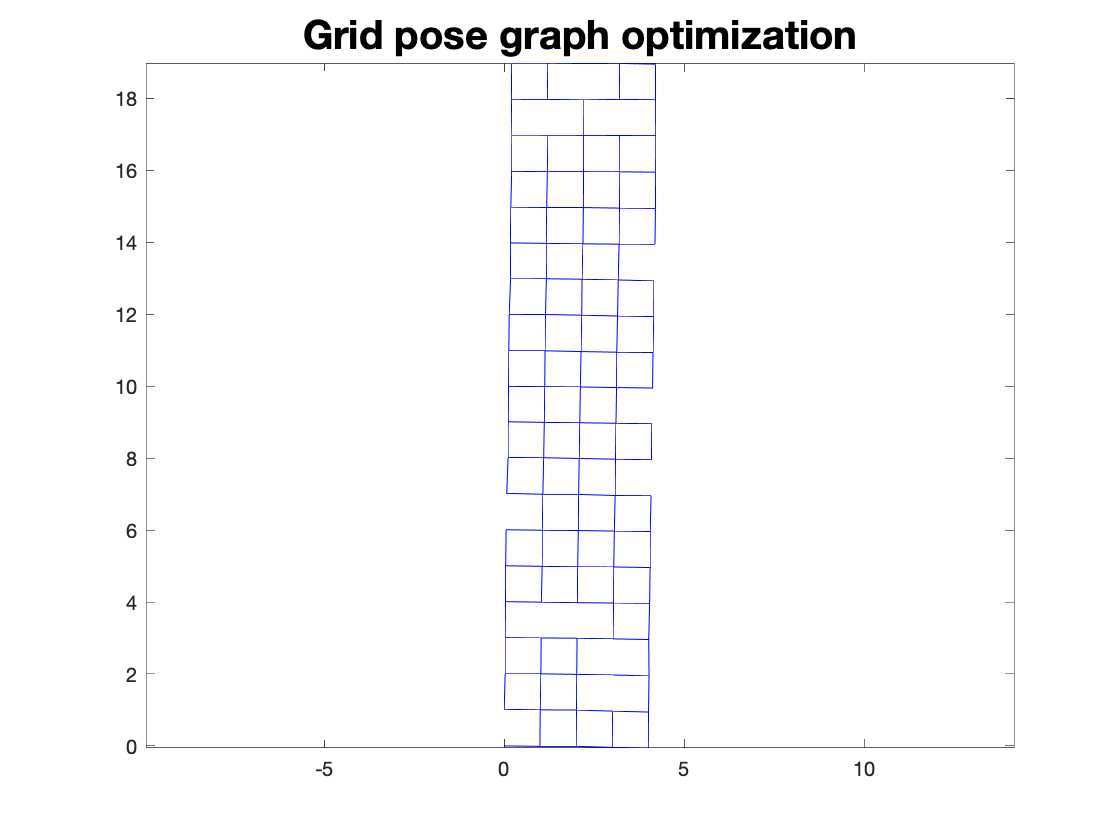

% visualize trajectories
plot_poses(xhat.t, xhat.R, sesync_measurements.edges, '-b', .25);
title('Grid pose graph optimization','FontSize',20)

### Solve Pose Graph Optimization on Real Datasets

The power of SE-Sync is not limited to simple 2D grid graphs. We now show that SE-Sync can solve large-scale real-world datasets in seconds. Note that we are using the Matlab version of SE-Sync. With the C++ version of SE-Sync, it can solve these problems in a fraction of second. The readers are encouraged to try out SE-Sync's C++ version for real-time applications.

#### 2D Pose Graph Optimization

We first use SE-Sync to solve a few 2D real-world examples, and compare its performance with local optimization (Gauss-Newton in this case).

The following code demonstrates the performance of SE-Sync:

% load real dataset from g2o file
% g2o_file = './PGO_data/intel.g2o';
g2o_file = './PGO_data/MIT.g2o';
% g2o_file = './PGO_data/CSAIL.g2o';

real_pgo_data = load_g2o_data(g2o_file);

% get some information about the data
nrNodes = max(max(real_pgo_data.edges));
nrEdges = length(real_pgo_data.kappa);
d = length(real_pgo_data.t{1});
fprintf('Processed input file %s: # of poses: %d, # of measurements: %d.\n', ...
    g2o_file, nrNodes, nrEdges);

Processed input file ./PGO_data/MIT.g2o: # of poses: 808, # of measurements: 827.


% call SE-Sync to solve
[SDPval, Yopt, xhat, Fxhat, SE_Sync_info, problem_data] = ...
    SE_Sync(real_pgo_data, Manopt_opts, SE_Sync_opts);



========== SE-Sync ==========

ALGORITHM SETTINGS:

SE-Sync settings:
 Initial level of Riemannian Staircase: 5
 Final level of Riemannian Staircase: 10
 Maximum number of iterations to perform for minimum eigenvalue computation in test for positive semidefiniteness: 2000 [default]
 Tolerance for accepting an eigenvalue as numerically nonnegative in optimality verification: 0.0001 [default]
 Using QR decomposition to compute orthogonal projection
 Initialization method: chordal [default]

Manopt settings:
 Stopping tolerance for norm of Riemannian gradient: 0.01
 Stopping tolerance for relative function decrease: 1e-05
 Maximum number of Hessian-vector products to evaluate in each truncated Newton iteration: 500
 Minimum number of trust-region iterations: 1
 Maximum number of trust-region iterations: 300
 Using incomplete zero-fill Cholesky preconditioner for truncated conjugate gradient inexact Newton step computations [default]


INITIALIZATION:

Constructing auxiliary data matrice

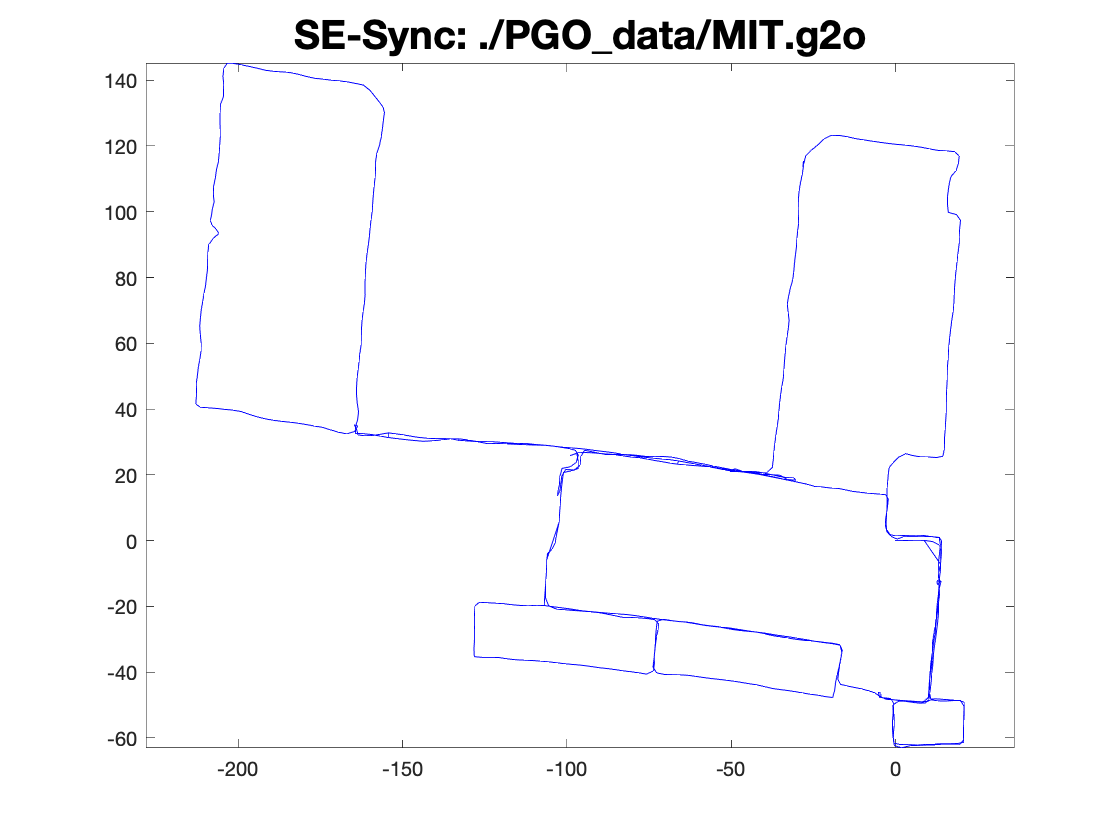

% Visualize the results of SE-Sync
plot_poses(xhat.t, xhat.R, real_pgo_data.edges, '-b', .25);
title(['SE-Sync: ',g2o_file],'Interpreter','none','FontSize',20)

The MIT dataset is very noisy dataset. However, as shown by the results above, SE-Sync still obtains an accurate estimate of the pose graph.

Next, we run local optimization using Gauss-Newton method to optimize the pose graph, with odometry as an initial guess:

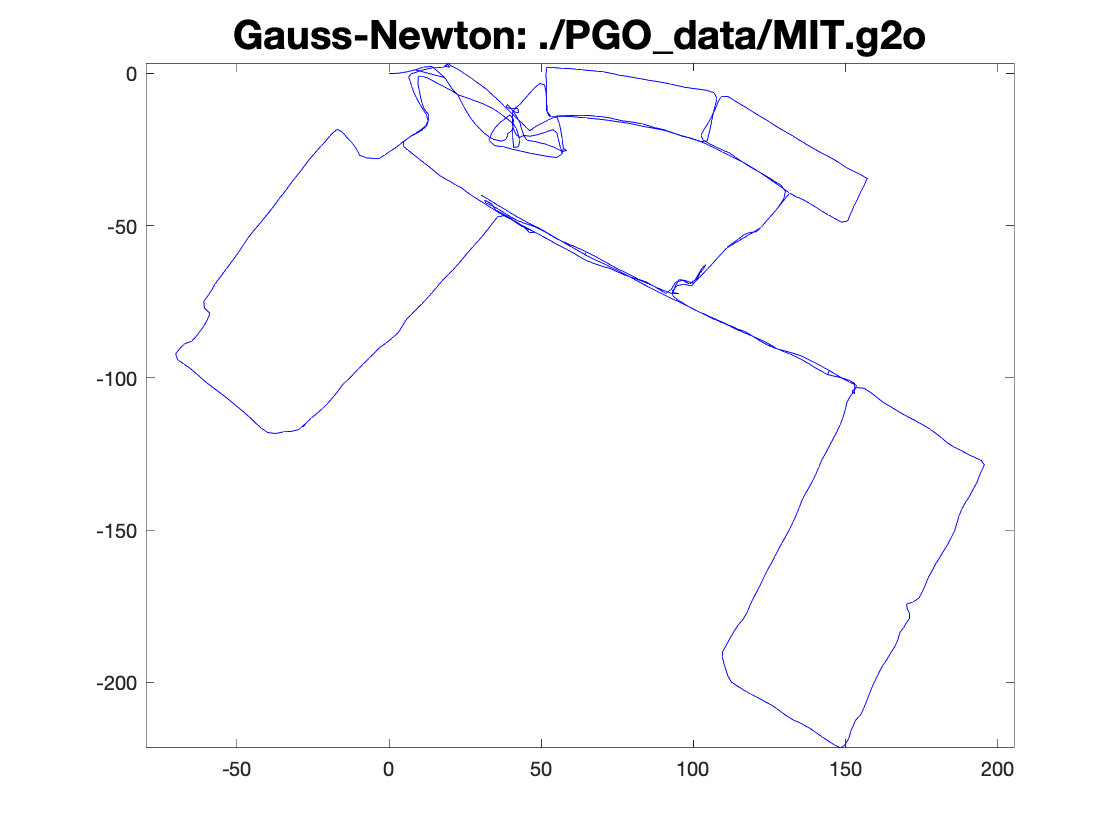

% read the same g2o dataset, in a different format
graph_real_data = graphDataset2D(g2o_file);
% Initialize the odometry
poseOdom = odometryFromEdges(graph_real_data.edges,nrNodes);
% Run Gauss-Newton method to optimize the pose graph
poseEst = refinePose2D(graph_real_data.edges, poseOdom(:,end)', poseOdom);
% convert the result for visualization
poseEst = pose2DvectToMat(poseEst);
xhat_GN.t = poseEst(:,1:d)';
xhat_GN.R = zeros(d,d*nrNodes);
for i = 1:nrNodes
    xhat_GN.R(:,blkIndices(i,d)) = rot2D(poseEst(i,d+1));
end
% visualize results of Gauss-Newton
plot_poses(xhat_GN.t, xhat_GN.R, real_pgo_data.edges, '-b', .25);
title(['Gauss-Newton: ',g2o_file],'Interpreter','none','FontSize',20)

We see that Guass-Newton local optimization fails on the MIT dataset.

#### 3D Pose Graph Optimization

As a last example, we wil show the power of SE-Sync on 3D pose graph optimization.

g2o_file = './PGO_data/sphere2500.g2o';
% g2o_file = './PGO_data/parking-garage.g2o';
% g2o_file = './PGO_data/rim.g2o';
% g2o_file = './PGO_data/torus3D.g2o';

real_pgo_data = load_g2o_data(g2o_file);

% get some information about the data
nrNodes = max(max(real_pgo_data.edges));
nrEdges = length(real_pgo_data.kappa);
d = length(real_pgo_data.t{1});
fprintf('Processed input file %s: # of poses: %d, # of measurements: %d.\n', ...
    g2o_file, nrNodes, nrEdges);

Processed input file ./PGO_data/sphere2500.g2o: # of poses: 2500, # of measurements: 4949.


% call SE-Sync to solve
[SDPval, Yopt, xhat, Fxhat, SE_Sync_info, problem_data] = ...
    SE_Sync(real_pgo_data, Manopt_opts, SE_Sync_opts);



========== SE-Sync ==========

ALGORITHM SETTINGS:

SE-Sync settings:
 Initial level of Riemannian Staircase: 5
 Final level of Riemannian Staircase: 10
 Maximum number of iterations to perform for minimum eigenvalue computation in test for positive semidefiniteness: 2000 [default]
 Tolerance for accepting an eigenvalue as numerically nonnegative in optimality verification: 0.0001 [default]
 Using QR decomposition to compute orthogonal projection
 Initialization method: chordal [default]

Manopt settings:
 Stopping tolerance for norm of Riemannian gradient: 0.01
 Stopping tolerance for relative function decrease: 1e-05
 Maximum number of Hessian-vector products to evaluate in each truncated Newton iteration: 500
 Minimum number of trust-region iterations: 1
 Maximum number of trust-region iterations: 300
 Using incomplete zero-fill Cholesky preconditioner for truncated conjugate gradient inexact Newton step computations [default]


INITIALIZATION:

Constructing auxiliary data matrice

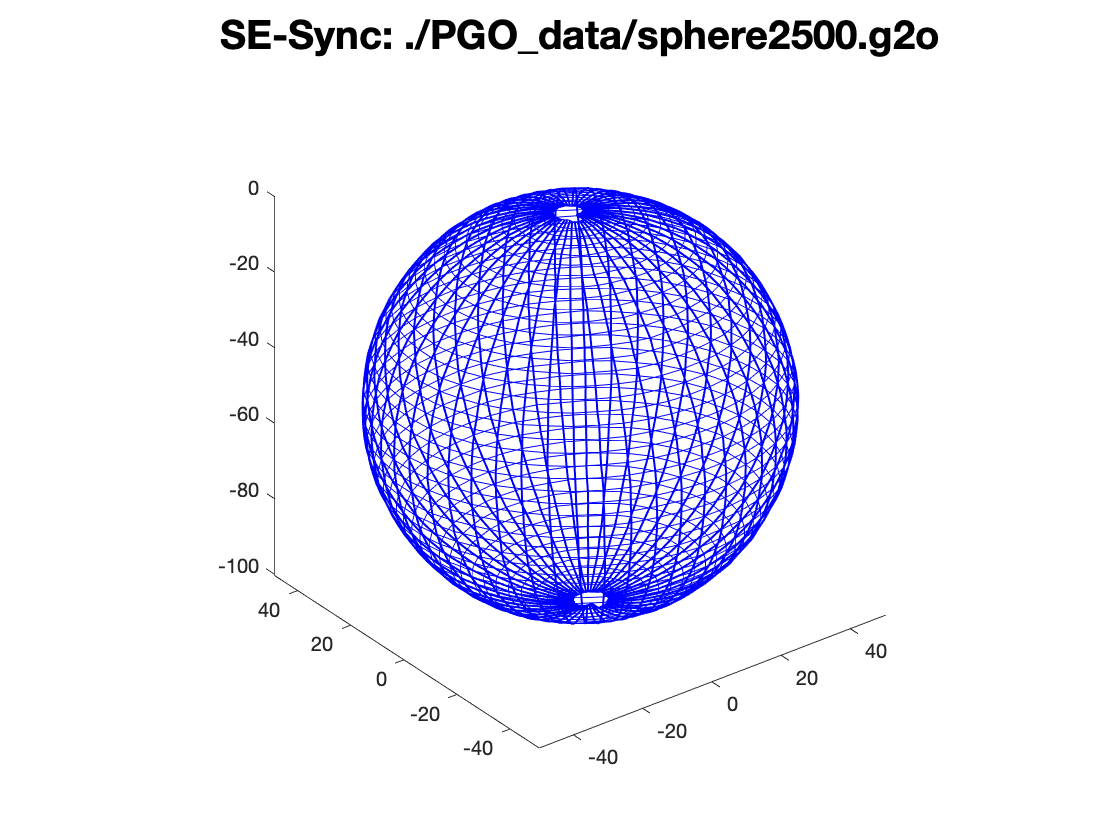

% Visualize the results of SE-Sync
plot_poses(xhat.t, xhat.R, real_pgo_data.edges, '-b', .25);
title(['SE-Sync: ',g2o_file],'Interpreter','none','FontSize',20)

## Appendix

### Semidefinite Relaxation

Brief introduction to Semidefinite Relaxation.

The original non-convex problem, a Quadratically-Constrained Quadratic Program (QCQP):


$$\text{min}_{x \in \mathbb{R}^n} \quad x^T Q x \\
\text{subject to} \quad x^T A_i x = a_i, \forall i=1,\dots,l \\
\quad \quad \quad \quad \quad x^T B_i x \geq b_i, \forall i = 1,\dots,m$$


This problem is NP-hard in general. 

How to do Semidefinite Relaxation? Construct matrx $Z = x x^T$, which by construction is Positive Semidefinite (PSD) and has rank 1: $Z \succeq 0, \text{rank}(Z) = 1$. Then the QCQP is equivalent to the following **rank-constrained Semidefinite Program (SDP)**:


$$\text{min}_{Z \in \mathbb{S}^n} \quad \langle Q, Z \rangle = \text{trace}(QZ)\\
\text{subject to} \quad \langle A_i, Z \rangle = a_i, \forall i=1,\dots,l \\
\quad \quad \quad \quad \quad \langle B_i, Z \rangle \geq b_i, \forall i = 1,\dots,m \\
\quad \quad \quad \quad \quad Z \succeq 0 \\
 \quad \quad \quad \quad \quad \text{rank}(Z) = 1$$


Then we relax the problem by dropping the rank constraint:


$$\text{min}_{Z \in \mathbb{S}^n} \quad \langle Q, Z \rangle = \text{trace}(QZ)\\
\text{subject to} \quad \langle A_i, Z \rangle = a_i, \forall i=1,\dots,l \\
\quad \quad \quad \quad \quad \langle B_i, Z \rangle \geq b_i, \forall i = 1,\dots,m \\
\quad \quad \quad \quad \quad Z \succeq 0 $$


which is convex SDP (strict generalization of Linear Programming (LP), do you see it?)

### Sums-of-Squares Relaxation

What is the original non-convex problem is **NOT a QCQP**? We can use Sums-of-Squares (SOS) Relaxation. 

The original non-convex problem is:


$$\text{min}_{x \in \mathbb{R}^n}  \quad f(x) \\
\text{subject to} \quad h_i(x)=0, \forall i=1,\dots,l \\
\quad \quad \quad \quad \quad g_i(x) \geq 0, \forall i=1,\dots,m$$


The SOS relaxation for this problem is:


$$\text{max}_{x \in \mathbb{x}^n, \gamma \in \mathbb{R}} \quad \gamma \\
\text{subject to} \quad f(x) - \gamma = s_0(x) + \sum_{i=1}^{l} s_i (x)g_i(x) + \sum_{i=1}^{m} \lambda_i(x) h_i(x) \\
\quad \quad \quad \quad \quad \quad s_i(x) = \sum_{j=1}^p q_{ij}^2(x) = [x]_d^T Q_i [x]_d, \forall i = 0,1,\dots,l, Q_i \succeq 0$$


This is a strict generalization of SDP relaxation (do you see this?) The SOS program can be converted to an SDP and solved in polynomial time.

## References

[1] Rosen, D. M., Carlone, L., Bandeira, A. S., & Leonard, J. J. (2018). SE-Sync: a certifiably correct algorithm for synchronization over the Special Euclidean group. *Intl. J. of Robotics Research*.

[2] Eriksson, A., Olsson, C., Kahl, F., & Chin, T.-J. (2018). Rotation averaging and strong duality. In *IEEE Conf. on Computer Vision and Pattern Recognition (CVPR)*.